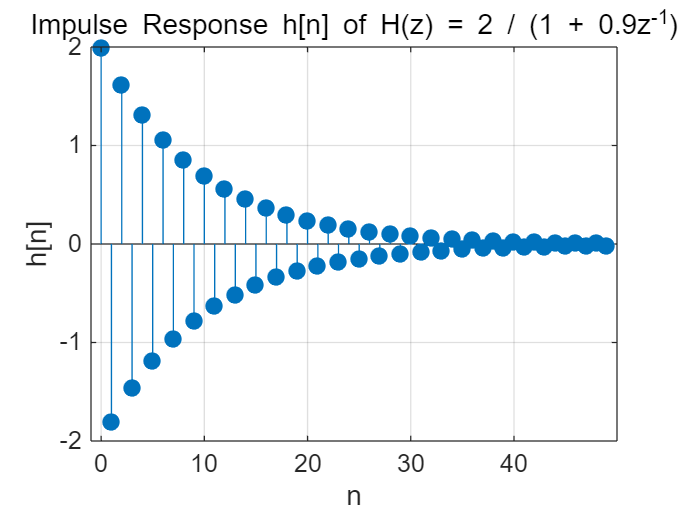

% 参数设置
N = 50;  % 显示前 N 个点
b = 2;           % 分子系数
a = [1 0.9];     % 分母系数，对应 H(z) = 2 / (1 + 0.9z^{-1})

% 生成单位冲激信号
delta = [1, zeros(1, N-1)];

% 使用 filter 得到冲激响应 h[n]
h = filter(b, a, delta);

% 绘图
stem(0:N-1, h, 'filled');
title('Impulse Response h[n] of H(z) = 2 / (1 + 0.9z^{-1})');
xlabel('n');
ylabel('h[n]');
grid on;

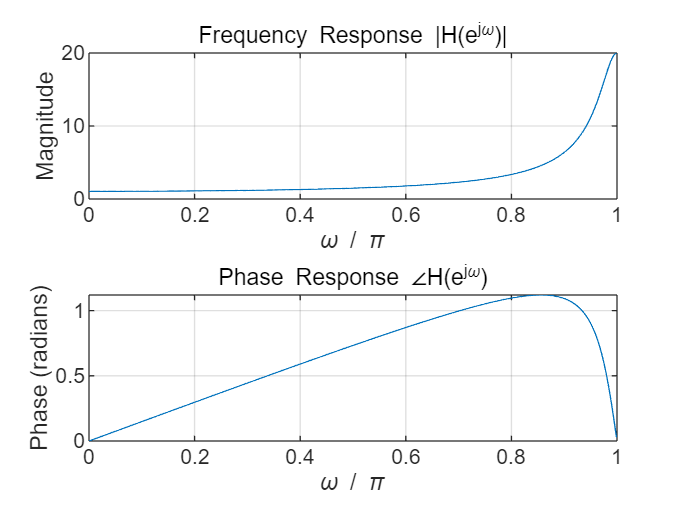



% 滤波器系数
b = 2;
a = [1 0.9];

% 使用 freqz 计算频率响应
[H, w] = freqz(b, a, 1024);  % 默认是 [0, pi] 区间，1024 个点

% 绘制幅度响应
figure;
subplot(2,1,1);
plot(w/pi, abs(H));
title('Frequency Response |H(e^{j\omega})|');
xlabel('\omega / \pi');
ylabel('Magnitude');
grid on;

% 绘制相位响应
subplot(2,1,2);
plot(w/pi, angle(H));
title('Phase Response ∠H(e^{j\omega})');
xlabel('\omega / \pi');
ylabel('Phase (radians)');
grid on;